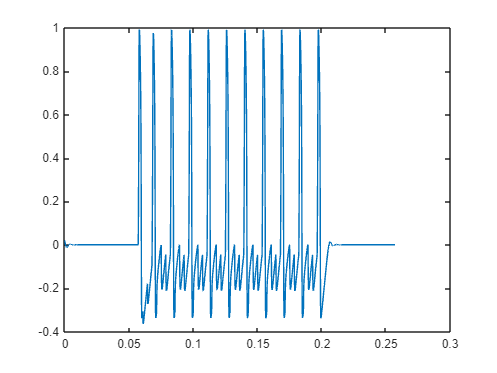

params.Tau = 2000.00;
params.TauR = 2000.00;
params.gc = 9.00;
params.NaX = 0.70;
params.alpha = 10.00;
params.b = 1.00;

% Soma parameters
paramsSoma = params;
paramsSoma.NaX = 1; % Always 1

% Initial conditions
initCon = [0.02; 0.02];

soma = Dendrite(0, paramsSoma, initCon);                     
dendrite = Dendrite(0, params, initCon);                     

% dendritic tree model                                       
tree = DendriteTreeModel();                          

% Add soma                                                   
tree.addDendrite(soma);               

%Add dendrites                                              
for i=1:1                                                   
    dendrite.ID = i;
    dendrite.params.NaX=0.01*i;
    tree.addDendrite(dendrite);       
end                                                          

%Define connections                                         
tree.addConnectionStr("0-1");     

fs = 64e+3;
h = 1/fs;
tmax = 1;
[t, sig] = supraStep(1, 7e+1, fs, 10, "type","bipolar", "numZeroPeriodsStart",4,"numZeroPeriodsEnd", 4);
%[t, sig, ~] = Chirp(1, tmax, fs, 50, 1000, "signal","square", "type","linear");
tree.verify();

tree.addStimuli(1, sig);

 [t, sol] = treeSolver(tree, max(t), h);
%[t, sol] = treeSolver(tree, tmax, h);
figure
plot(t, sol(1, :))


classifyFiringPattern(sol(1, :), fs, 0.8)

ans = 'NASP/STEADY_STATE.'